%% Test script for construct_avl 

clear
clc

% ---------------------------
% Define aircraft parameters
% ---------------------------

obj = struct();

% Reference geometry
obj.WingArea = 800; % m^2
obj.CMAC = 5; % MAC
obj.WingSpan = 50.0; % span

% Wing placement
obj.WingStart = 30.0;
obj.WingHeight = 0.0;
obj.AOA_incident = 2.0;

% Wing geometry
obj.RootChord = 15.0;
obj.TipChord  = 1.8;
obj.SweepAngle= 32; % Degrees
obj.DihedralAngle= 4; % Degrees
obj.Kinky = 8;

% Wing geometery - X/Z offsets
[Tipx,Tipz] = Unconventional.automation.leading_offset(obj.SweepAngle,obj.DihedralAngle,(obj.WingSpan./2));
[Kinkx,Kinkz] = Unconventional.automation.leading_offset(obj.SweepAngle,obj.DihedralAngle,obj.Kinky);

obj.Tipx = Tipx;
obj.Tipz = Tipz;

obj.KinkChord  = obj.RootChord - Kinkx;
obj.Kinkx = Kinkx;
obj.Kinkz = Kinkz;

% Control surfaces
obj.FlapStart    = 0.75;
obj.AileronStart = 0.75;

% ---------------------------
% Horizontal tail
% ---------------------------

obj.HStabStart = 60.0;

obj.HRootChord = 6.0;
obj.HTipChord  = 1.5;

obj.TailSpan = 25.0;
obj.HalfTailSpan = obj.TailSpan/2;

obj.HSweepAngle= 40; % Degrees
obj.HDihedralAngle= 2; % Degrees

% Wing geometery - X/Z offsets
[HTailx,HTailz] = Unconventional.automation.leading_offset(obj.HSweepAngle,obj.HDihedralAngle,(obj.TailSpan./2));

obj.HTipx = HTailx;
obj.HTipz = HTailz;

obj.ElevatorHinge = 0.7;

% ---------------------------
% Vertical tail
% ---------------------------

obj.VStabStart = 61;

obj.VRootChord = 5.0;
obj.VTipChord  = 1.8;

obj.VSweepAngle = 40;

[VTailx,VTailz] = Unconventional.automation.leading_offset(obj.VSweepAngle,0.0,(obj.TailSpan./2));

obj.VTailSpan = 16.0;
obj.VTipX = VTailx;

% Rudder hinge
obj.RudderHinge = 0.7;

% ---------------------------
% Airfoils
% ---------------------------

obj.HorAerofoil = 'naca0012.dat';
obj.VerAerofoil = 'naca0012.dat';

WingAirfoil = 'SC(2)-0610.dat';

% ---------------------------
% Flight condition
% ---------------------------

Mach = 0.78;
Alt  = 11000;

% ---------------------------
% Run AVL file generator
% ---------------------------

Unconventional.automation.construct_avl(obj, Mach, Alt, WingAirfoil);

disp('AVL geometry file generated: unconventional.avl')

AVL geometry file generated: unconventional.avl



% ------------------------------------------------
% Additional Aircraft Parameters (Drag + Performance)
% ------------------------------------------------

%% Aerodynamic properties

obj.tc       = 0.12;   % Wing thickness-to-chord ratio
obj.tc_ht    = 0.10;   % Horizontal tail thickness ratio
obj.tc_vt    = 0.10;   % Vertical tail thickness ratio

obj.CLmax_clean = 1.5; % Clean configuration
obj.CLmax_flap  = 2.6; % Landing configuration

%% Fuselage geometry

obj.FuselageLength   = 75;   % m
obj.FuselageDiameter = 7.0;  % m

%% Engine / nacelle parameters

obj.N_eng = 2;               % Number of engines

obj.NacelleLength   = 8.0;   % m
obj.NacelleDiameter = 3.5;   % m

%% Aircraft mass properties

obj.MTOM    = 490000;  % kg (Maximum takeoff mass)
obj.Payload = 85000;   % kg
obj.OEW     = 250000;  % kg

%% Derived aerodynamic quantities

obj.AR = obj.WingSpan^2 / obj.WingArea;         % Aspect ratio
obj.WingLoading = (obj.MTOM * 9.81) / obj.WingArea; % Wing loading (N/m^2)

%% Cruise condition

obj.CruiseMach = 0.78;
obj.CruiseAlt  = 11000;

%% Performance reference

obj.g = 9.81;  % Gravity

CD0 = Unconventional.aerodynamics.testdragbuildup(obj,11000,0.78);

ans = 0.0061

ans = 0.0023

ans = 7.1873e-04

ans = 4.2856e-04

ans = 0.0020

ans = 0.0020

ans = 1.0000e-03

Estimated CDwing = 0.0061464
Estimated CDfuselage = 0.0023146
Estimated CDht = 0.00071873
Estimated CDvt = 0.00042856
Estimated CDnacelle = 0.002
Estimated CDlg = 0.002
Estimated CDmisc = 0.001
Estimated CD0 = 0.014608



% ---------------------------
% Run AVL
% ---------------------------

runDir  = 'C:\Users\OscarAntill\OneDrive - University of Bristol\group3\+Unconventional\+automation\runs';
avlPath = fullfile(runDir, 'avl352.exe');

disp(isfile(fullfile(runDir,'avl352.exe')))

   1



disp(isfile(fullfile(runDir,'run.cmd')))

   1



disp(isfile(fullfile(runDir,'unconventional.avl')))

   1




cd(runDir)
[status,cmdout] = system(['"' avlPath '" < run.cmd > polar_output.txt']);
disp(status)

     2



disp(cmdout)

At line 145 of file ../src/userio.f (unit = 5, file = 'stdin')
Fortran runtime error: End of file

Error termination. Backtrace:
#0  0xacb581f3 in ???
#1  0xacb4ff41 in ???
#2  0xacb4a75b in ???
#3  0xacb51664 in ???
#4  0xacb55a31 in ???
#5  0xacb55419 in ???
#6  0xacb60d7c in ???
#7  0xacb60573 in ???
#8  0xacb4e2d2 in ???
#9  0xacaded11 in ???
#10  0xaca7aaf4 in ???
#11  0xaca74f3e in ???
#12  0xaca75ca4 in ???
#13  0xaca71317 in __tmainCRTStartup
	at C:/M/B/src/mingw-w64/mingw-w64-crt/crt/crtexe.c:259
#14  0xaca71425 in mainCRTStartup
	at C:/M/B/src/mingw-w64/mingw-w64-crt/crt/crtexe.c:179
#15  0xfa84e8d6 in ???
#16  0xfb5cc48b in ???
#17  0xffffffff in ???



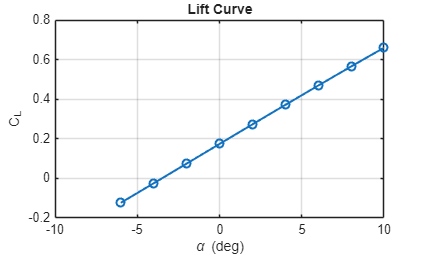


% ---------------------------
% Extract AVL polar data
% ---------------------------

filename = fullfile(runDir, 'polar_output.txt');   % AVL output file
txt = fileread(filename);

% Extract AoA
alpha = regexp(txt,'Alpha\s*=\s*([-+]?\d*\.?\d+)','tokens');
alpha = cellfun(@(x) str2double(x{1}), alpha);

% Extract CL values
CL = regexp(txt,'CLtot\s*=\s*([-+]?\d*\.?\d+)','tokens');
CL = cellfun(@(x) str2double(x{1}), CL);

% Extract CD values
CD = regexp(txt,'CDtot\s*=\s*([-+]?\d*\.?\d+)','tokens');
CD = cellfun(@(x) str2double(x{1}), CD);

% Make sure they align
n = min([length(alpha), length(CL), length(CD)]);
alpha = alpha(1:n);
CL = CL(1:n);
CD = CD(1:n);

% Remove duplicates (AVL sometimes repeats last case)
[alpha, uniqueIdx] = unique(alpha);
CL = CL(uniqueIdx);
CD = CD(uniqueIdx);

%% Plot Lift Curve
figure
plot(alpha, CL, 'o-','LineWidth',1.5)
xlabel('\alpha (deg)')
ylabel('C_L')
grid on
title('Lift Curve')

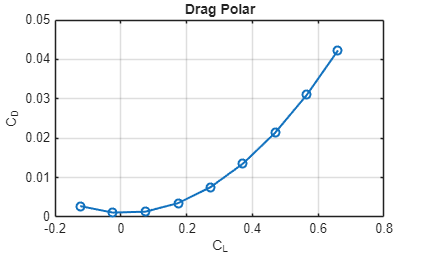


%% Plot Drag Polar
figure
plot(CL, CD, 'o-','LineWidth',1.5)
xlabel('C_L')
ylabel('C_D')
grid on
title('Drag Polar')